# Plotting a Hurricane

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

aHurr = readtable("./data/aHurrData.csv");
head(aHurr(:, 1:end-1))

    Number         Timestamp          Country    Windspeed    Pressure    Location    HurrCat
    ______    ____________________    _______    _________    ________    ________    _______

      13      22-Oct-1998 00:00:00    {'N/A'}       35          1002      {'Sea'}        0   
      13      22-Oct-1998 06:00:00    {'N/A'}       35          1002      {'Sea'}        0   
      13      22-Oct-1998 12:00:00    {'N/A'}       35          1002      {'Sea'}        0   
      13      22-Oct-1998 18:00:00    {'N/A'}       40          1001      {'Sea'}        0   
      13      23-Oct-1998 00:00:00    {'N/A'}       46          1000      {'Sea'}        0   
      13      23-Oct-1998 06:00:00    {'N/A'}       52           999      {'Sea'}        0   
      13 

ws = aHurr.Windspeed;
pr = aHurr.Pressure;
cat = aHurr.HurrCat;
ts = aHurr.Timestamp;
elapsedTime = aHurr.elapsedTime;

## Task 1

Data from one hurricane has been loaded into the workspace.  The wind speed and pressure measurements along with the hurricane category and timestamp have been extracted as numeric vectors.

You can use the scatter function to create a scatter plot with markers of a specified size and color.

`scatter``(``x``,``y``,``sz``,``col``)`

The size and color inputs are optional.  There is also a fifth optional input to specify that the markers should be filled in.

`scatter``(``x``,``y``,``sz``,``col``,``"filled"``)`

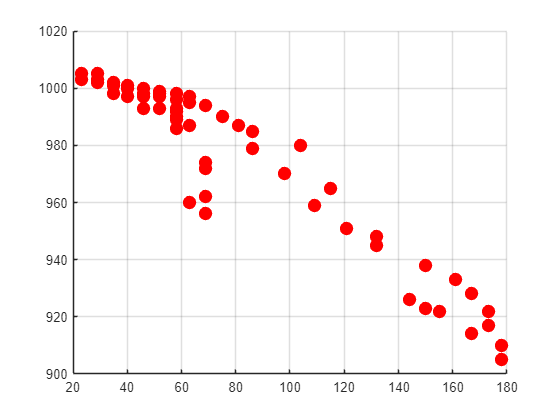

scatter(ws, pr, 100, "r", "filled")
grid on

## Task 2

When markers are overlapping, you may be able to see them better by setting the transparency with the `MarkerFaceAlpha` property.

`scatter``(``x``,``y``,``sz``,``col``,``"filled"``,``...`

    `"MarkerFaceAlpha"``,``a``)`

The value `a` can be from 0 (fully transparent) to 1 (opaque).  

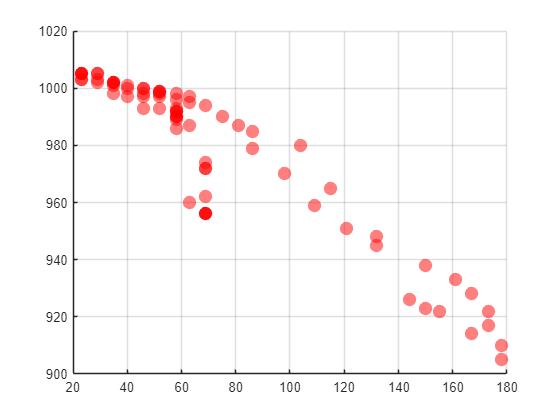

scatter(ws, pr, 100, "r", "filled", "MarkerFaceAlpha", .5)
grid on

## Task 3

The `sz` input can be a vector of positive integers that specifies a different size for each marker.

The `cat` variable contains the category of the hurricane for each reading.  When the hurricane was classified as a tropical storm or depression, it was coded as a `0`.  To use this variable for the size of the markers, you will need to modify it.

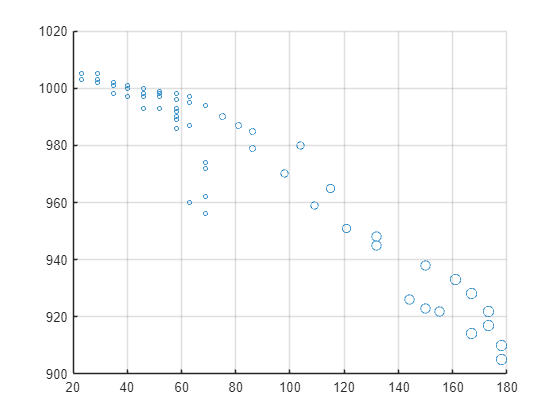

szCat = (cat+1)*10;
scatter(ws, pr, szCat)
grid on

## Task 4

Similarly, the `col` input can be a vector to use color to relay information.

The variable `elapsedTime` contains the time (in days) since the first reading.

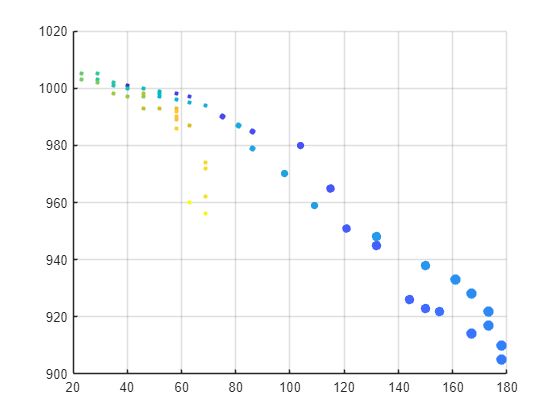

scatter(ws, pr, szCat, elapsedTime, "filled")
grid on

## Task 5

You can add a color bar to the plot with the `colorbar` command.

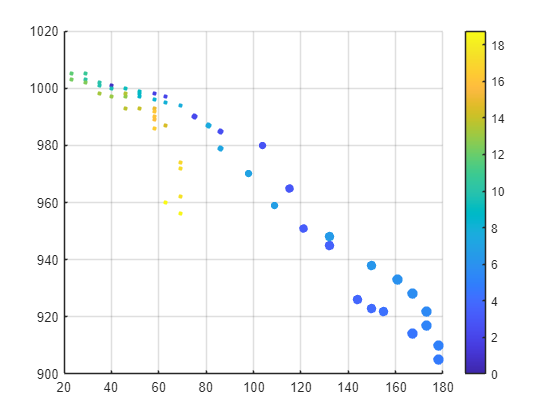

colorbar

## Task 6

You can kind of see that the highest winds occurred in the first few days of the hurricane.

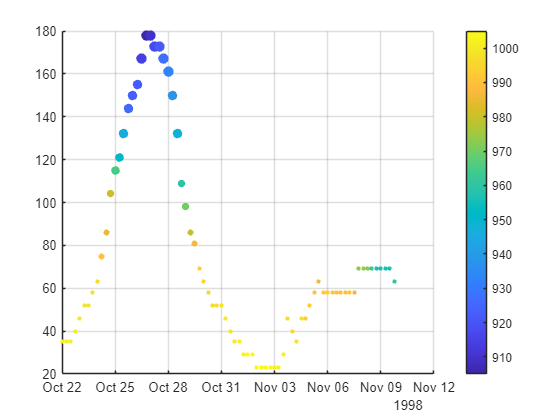

scatter(ts, ws, szCat, pr, "filled")
colorbar
grid on